simTime = 60;    % in seconds
updateRate = 2;  % in Hz


scene = uavScenario(ReferenceLocation=[40.707088 -74.012146 0]);
xlimits = [0 300]; % Increase range of xlimits
ylimits = [0 300]; % Increase range of ylimits
color = [0.6 0.6 0.6];
terrainInfo = addMesh(scene,"terrain",{"gmted2010",xlimits,ylimits},color,Verbose=true)

Error using uavScenario/addMesh
'Verbose' is not a recognized parameter. For a list of valid name-value pair arguments, see the documentation for this function.

xlimits = [5 300]; % Increase range of xlimits
ylimits = [5 300]; % Increase range of ylimits
color = [0 1 0];
osmInfo = addMesh(scene,"buildings",{"southboulder.osm",xlimits,ylimits,"auto"},color,Verbose=true)

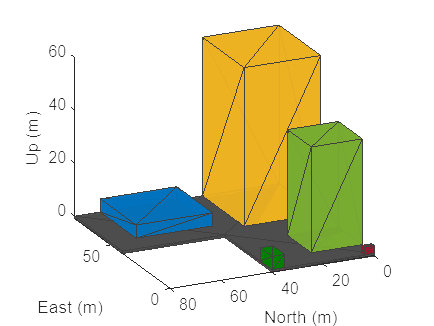

show3D(scene);
axis equal
view([-115 20])

% ------------ Waypoints-------------------------- 
x = 300:-1:0; % Increase range of x
y = 300:-1:0; % Increase range of y
z = 300*ones(1,length(x)); 
waypoints = [x' y' z'];

orientation_eul = [0 0 0];
orientation_quat = quaternion(eul2quat(orientation_eul)); 
orientation_vec = repmat(orientation_quat,length(x),1);

 time = 0:(simTime/(length(x)-1)):simTime;

trajectory = waypointTrajectory("Waypoints",waypoints,"Orientation",orientation_vec, ...
    "SampleRate",updateRate,"ReferenceFrame","ENU","TimeOfArrival",time); 

initial_pose = [-20 -20 100 1 0 0 0]; 

plat = uavPlatform("UAV",scene,"Trajectory",trajectory,"ReferenceFrame","ENU"); 
updateMesh(plat,"quadrotor",{4},[1 0 0],eye(4)); 

lidarmodel = uavLidarPointCloudGenerator("AzimuthResolution",0.6, ...
    "ElevationLimits",[-90 -20],"ElevationResolution",2.5, ...
    "MaxRange",200,"UpdateRate",2,"HasOrganizedOutput",true);

lidar = uavSensor("Lidar",plat,lidarmodel,"MountingLocation",[0 0 -1],"MountingAngles",[0 0 0]); 

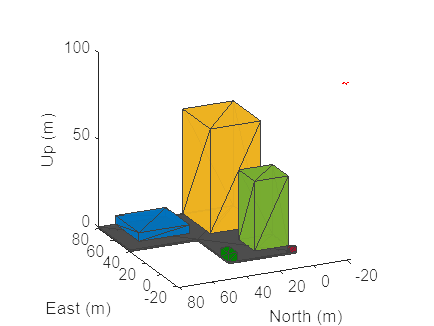

[ax,plotFrames] = show3D(scene);
xlim([-15 80]);
ylim([-15 80]);
zlim([0 80]);
view([-115 20]); 
axis equal 
hold on

colormap('jet');
ptc = pointCloud(nan(1,1,3));
scatterplot = scatter3(nan,nan,nan,1,[0.3020 0.7451 0.9333],...
    "Parent",plotFrames.UAV.Lidar);
scatterplot.XDataSource = "reshape(ptc.Location(:,:,1), [], 1)";
scatterplot.YDataSource = "reshape(ptc.Location(:,:,2), [], 1)";
scatterplot.ZDataSource = "reshape(ptc.Location(:,:,3), [], 1)";
scatterplot.CDataSource = "reshape(ptc.Location(:,:,3), [], 1) - min(reshape(ptc.Location(:,:,3), [], 1))";
hold off; 


lidarSampleTime = [];
pt = cell(1,((updateRate*simTime) +1)); 
ptOut = cell(1,((updateRate*simTime) +1)); 

map3D = occupancyMap3D(1);

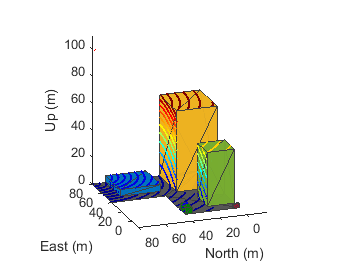

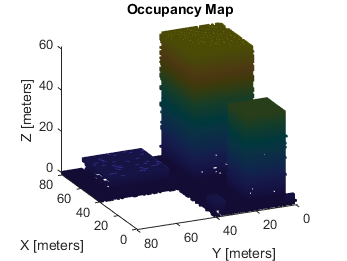

setup(scene); 

ptIdx = 0;
while scene.IsRunning
    ptIdx = ptIdx + 1;
    % Read the simulated lidar data from     the scenario
    [isUpdated,lidarSampleTime,pt{ptIdx}] = read(lidar);

    if isUpdated
        % Get Lidar sensor's pose relative to ENU reference frame.
        sensorPose = getTransform(scene.TransformTree, "ENU","UAV/Lidar",lidarSampleTime);
        % Process the simulated Lidar pointcloud.
        ptc = pt{ptIdx};
        ptOut{ptIdx} = removeInvalidPoints(pt{ptIdx});
        % Construct the occupancy map using Lidar readings.
        insertPointCloud(map3D,[sensorPose(1:3,4)' tform2quat(sensorPose)],ptOut{ptIdx},500);

        figure(1)
        show3D(scene,"Time",lidarSampleTime,"FastUpdate",true,"Parent",ax);
        xlim([-15 80]);
        ylim([-15 80]);
        zlim([0 110]);
        view([-110 20]);
        
        refreshdata
        drawnow limitrate
    end
    
    % Show map building real time 
    figure(2)
    show(map3D);
    view([-115 20]);
    axis equal 
    
    advance(scene);
    updateSensors(scene); 
    
end